%% Aircraft component weight equations
% Units: lb, ft, ft^2, gal, ft^3, inches where stated. Angles in DEGREES.
% NaN = value you still need to fill in. Values given in the nomenclature
% (e.g. K factors) are set to their "otherwise" default of 1.0 - change as needed.
clear; clc;

% ------------------------------------------------------------------------
%  VARIABLES
%  ------------------------------------------------------------------------


% --- Crew / payload ---
N_c         = 8;   % Number of crew
N_p         = 158;   % Total number of persons onboard (crew + passengers)
N_seat_E    = 90;   % Number of seats of given type
N_seat_PE   = 36;   % Number of seats of given type
N_seat_B    = 24;   % Number of seats of given type

% values from other code -------------------------------------------- [edit here]
xacw = 32.0; % longitudinal position of the aerodynamic centre of the wing from the nose [m] [guess]
xach = 55; % longitudinal position of the aerodynamic centre of the H-tail from the nose [m] [guess]
xacv = 55; % longitudinal position of the aerodynamic centre of the V-tail from the nose [m] [guess]

%wing
MAC = 7.265096734237829;
b = 64.976918978972833;
%H-stab
V_h = 1;
%V-stab
V_v = 0.09;

% --- Geometry: wing ---
AR          = 10;   % Wing aspect ratio
Bw          = 3.281*64.976918978972833;   % Wing span (ft)
Sw          = (3.281)^2*421.90;   % Reference wing area (ft^2) [u sure?]
Sw_m2 = 421.90; % Reference wing area
disp("Sw = "+ (Bw.^2)./(AR.*((3.281)^2))) % test

Sw = 422.2


Scsw        = (3.281)^2*47.44;   % Area of wing mounted control surfaces (ft^2)
lambda      = 0.253;   % Wing taper ratio
Lambda_w    = 32.42;   % Wing quarter chord sweep (deg)
tc_root     = 0.14;   % (t/c)_root, wing root thickness to chord ratio

% --- Geometry: horizontal tail ---

S_ht        = (3.281)^2*(V_h*Sw_m2*MAC)./(xach-xacw);   % Horizontal tailplane area (ft^2) [guess]
AR_h        = 4;   % Horizontal tailplane aspect ratio [edit]
B_t         = sqrt(AR_h*S_ht);   % Horizontal tailplane span (ft) [guess]
S_e         = 23.75*(3.281)^2;   % Elevator area (ft^2) [guess]
Lambda_ht   = 36;   % Horizontal tailplane quarter chord sweep (deg)
L_ht        = 3.281*(xach-xacw);   % Length from wing a.c. to horizontal tail a.c. (ft) [guess - edit]
Ht_Hv       = 0;   % Horizontal tail location on vertical tail (0.0 fuselage mounted, 1.0 T-tail)
tr_h = 0.4; %taper ratio of the hstab
c_root_h = 2*S_ht / (B_t*(1 + tr_h));
c_tip_h  = tr_h * c_root_h;
MAC_h = (2/3) * c_root_h * (1 + tr_h + tr_h^2) / (1 + tr_h);

% --- Geometry: vertical tail ---
AR_v        = 1.7;   % Vertical tailplane aspect ratio
S_vt        = (3.281)^2*(V_v*Sw_m2*b)./(xacv-xacw);   % Vertical tailplane area (ft^2)
B_Vt         = sqrt(AR_v*S_vt);   % Horiziontal tailplane span (ft) [guess]
Lambda_vt   = 40;   % Vertical tailplane quarter chord sweep (deg)
L_vt        = 3.281*(xacv-xacw);   % Length from wing a.c. to vertical tail a.c. (ft) [guess - edit]
tc_root_v   = 0.11;   % (t/c)_root_v, vertical tail root thickness to chord ratio [needs to be determined properly----]
tr_v = 0.35; %taper ratio of the vstab
c_root_v = 2*S_vt / (B_Vt*(1 + tr_v));
c_tip_v  = tr_v * c_root_v;
MAC_v = (2/3) * c_root_v * (1 + tr_v + tr_v^2) / (1 + tr_v);

% --- Geometry: fuselage / nacelle ---
D           = 5.9063; % Maximum fuselage diameter (m)
D_ft        = 3.281*D;   % Maximum fuselage diameter (ft)
F_w         = 3.281*2.9;   % Fuselage width at horizontal tail intersection (ft) [guess]
L_f_m       = 63.191; % Total fuselage length (m)
L_f         = 3.281*L_f_m;   % Total fuselage length (ft)
x_tailcap_joint_m = 0.517;                % Tail-cap structural joint location (m) [confirmed]
x_radome_joint_m  = 1.795;                % Radome structural joint location (m) [confirmed]
L           = 3.281*(L_f/3.281- x_tailcap_joint_m - x_radome_joint_m);  % Fuselage structural length (ft) [confirmed]
S_f         = 3.281^2*1040;   % Fuselage wetted area (ft^2) [guess]
N_Lt        = 21.19;   % Nacelle length (ft)
N_w         = 10.96;   % Nacelle width (ft)
S_n         = 653;   % Nacelle wetted area (ft^2)
A_fc        = NaN;   % Cargo hold floor area (ft^2)
V_pr        = 3.281^3*1048.2;   % Volume of pressurized sections (ft^3) [estimate]

% --- Propulsion ---
N_en        = 2;   % Number of engines
L_ec        = 255.188;   % Engine controls routing distance, engine to cockpit - to tail if multiengine (ft)

% --- Fuel system ---
V_t         = 123.29*264.172;  % Total volume of fuel tanks (gal)
rho_f       = 775./16.018;     %density of the fuel [lb/ft^3]
W_fuel      = rho_f*V_t./7.48; %weight of the fuel [lbs]
V_i         = V_t;           % Integral fuel tank volume (gal)
V_p         = 0;   % Self sealing tank volume (gal)
N_t         = 3;   % Total number of fuel tanks

% --- Weights ---
W_dg        = 2.20462*253648.40;   % Design gross weight (lb) [guess]
W_l         = W_dg-W_fuel*0.70;   % Landing design gross weight (lb) (assuming that we only have 30% of the total fuel left) [123]
W_en        = 7549*2.205;   % Engine weight (lb) (x2 as two engines)
W_APU       = 762;   % Uninstalled APU weight (lb)
W_c         = (40000+N_seat_B*35+N_seat_PE*28+N_seat_E*23)*2.205;   % Maximum cargo weight (lb)
W_pas       = 84*150*2.205; %maximum passenger weight (lb)
TW0         = 0.288;  % Thrust-to-weight ratio T/W0
W_uav       = 0.02*(W_dg*(0.32 + 0.66*W_dg^(-0.13)*AR^0.30*TW0^0.06*(W_dg/Sw)^(-0.05)*0.82^0.05)*1.0);   % Uninstalled avionics weight, typ. 800-1400 (lb)
W_seat_E    = 35*2.205;   % Weight of single economy seat (lb)
W_seat_PE   = 80*2.205;   % Weight of single premium economy seat (lb)
W_seat_B    = 175*2.205;   % Weight of single business class seat (lb)

% --- Load factors ---
N_z         = 1.5*2.5;   % Ultimate load factor = 1.5 x limit load factor
N_gear      = 3.0;   % Ratio of avg total main gear load on landing to max landing weight; typ. 2.7-3
N_l         = 1.5*N_gear;   % Ultimate landing gear load factor

% --- Landing gear ---
L_m         = 350 / 2.54;   % Main landing gear length (in) [guess]
L_n         = 350 / 2.54;   % Nose landing gear length (in) [guess]
N_mw        = 12;   % Number of main wheels
N_nw        = 2;   % Number of nose wheels
N_mss       = 2;   % Number of main gear shock struts
V_s         = 48.82 * 3.281;   % Landing stall speed (ft/s) 
 
% --- Controls / systems --- [123] 
N_f         = 7;   % Number of functions performed by controls; typ. 4-7
N_m         = 0;   % Number of mechanical functions performed by controls; typ. 0-2
S_cs        = (20.63+26.39+23.75+20.39)*3.281^2;   % Total control surface area (ft^2)
R_kva       = 400;   % System electrical rating; typ. 40-60 for transports (kVA)
L_a         = L_ec;   % Electrical routing distance, generators to avionics to cockpit (ft)
N_gen       = 4;  % Number of generators; typ. = N_en (+1?)

% --- Empirical K factors (defaults = 1.0 "otherwise" case) ---
K_buf       = 5.68;   % 1.02 short ranges; 5.68 very long ranges
K_door      = 1.18;   % 1.0 no cargo door; 1.06 one side door; 1.12 two side doors or aft clamshell; 1.25 two side + aft clamshell
K_lav       = 1.11;   % 1.11 long range; 0.31 short range; 3.9 business jets
K_Lg        = 1.0;   % 1.12 fuselage mounted landing gear; 1.0 otherwise
K_mp        = 1.0;   % 1.126 kneeling main gear; 1.0 otherwise
K_ng        = 1.0;   % 1.017 pylon mounted nacelle; 1.0 otherwise
K_np        = 1.0;   % 1.15 kneeling nose gear; 1.0 otherwise
K_r         = 1.0;   % 1.133 reciprocating engines; 1.0 otherwise
K_tp        = 1.0;   % 0.793 turboprop; 1.0 otherwise
K_uht       = 1.0;   % 1.143 all-moving tail; 1.0 otherwise
K_p         = 1.0;   % 1.4 engine with propeller; 1.0 otherwise
K_tr        = 1.0;   % 1.18 jet with thrust reversers; 1.0 otherwise

% --- Derived quantities from the nomenclature ---
K_ws        = 0.75*((1 + 2*lambda)/(1 + lambda))*Bw*tand(Lambda_w)/L;  % wing sweep factor
K_y         = 0.3*L_ht;          % Pitching radius of gyration (ft)
K_z         = L_vt;              % Yaw radius of gyration (ft)
I_y         = W_dg*K_y^2;        % Pitching moment of inertia (lb ft^2), W_o ~ W_dg
W_enc       = 2.331*K_p*K_tr*W_en^0.901;  % Weight of engine and contents (lb)

% --- Material Factors ---

% wing
MF_w = 0.78;

% tail plane
MF_tp = 0.75;

% fuselage/nacelle
MF_F = 0.85;

% Landing gear
MF_lg = 0.88;

% ------------------------------------------------------------------------
%  WEIGHT EQUATIONS
%  ------------------------------------------------------------------------

% Aircraft wings
W_w = (0.0051 * (W_dg*N_z)^0.557 * Sw^0.649 * AR^0.5 * (1 + lambda)^0.1 * Scsw^0.1) ...
      ./ (cosd(Lambda_w) * tc_root^0.4);
W_w = MF_w*W_w; % Fudge factor for composites (from raymer)

% Horizontal tail plane
W_ht = (0.0379 * K_uht * W_dg^0.639 * N_z^0.1 * S_ht^0.75 * K_y^0.704 * AR_h^0.166 ...
       * (1 + S_e/S_ht)^0.1) ...
       ./ ((1 + F_w/B_t)^0.25 * L_ht * cosd(Lambda_ht));
W_ht = MF_tp*W_ht; % Fudge factor for composites (from raymer)

% Vertical tail plane
W_vt = (0.0026 * (1 + Ht_Hv)^0.225 * W_dg^0.556 * N_z^0.536 * S_vt^0.5 * K_z^0.875 * AR_v^0.35) ...
       ./ (L_vt^0.5 * cosd(Lambda_vt) * tc_root_v^0.5);
W_vt = MF_tp*W_vt; % Fudge factor for composites (from raymer)

% Fuselage
W_fus = 0.3280 * K_door * K_Lg * (W_dg*N_z)^0.5 * L^0.25 * S_f^0.302 * (1 + K_ws)^0.04 * (L/D_ft)^0.1;
W_fus = MF_F*W_fus; % Fudge factor for composites (from raymer)

% Main landing gear
W_mlg = 0.0106 * K_mp * W_l^0.888 * N_l^0.25 * L_m^0.4 * N_mw^0.321 * V_s^0.1 / N_mss^0.5;
W_mlg = MF_lg*W_mlg; % Fudge factor for composites (from raymer)

% Nose landing gear
W_nlg = 0.032 * K_np * W_l^0.646 * N_l^0.2 * L_n^0.5 * N_nw^0.45;
W_nlg = MF_lg*W_nlg; % Fudge factor for composites (from raymer)

% Nacelle
W_inl = 0.6724 * K_ng * N_Lt^0.1 * N_w^0.294 * N_z^0.119 * W_enc^0.611 * N_en^0.984 * S_n^0.224;
W_inl = MF_F*W_inl; % Fudge factor for composites (from raymer)

% Engine controls
W_ec = 5*N_en + 0.8*L_ec;

% Engine (pneumatic) starter
W_es = 49.19 * (N_en*W_en/1e3)^0.541;

% Fuel system
W_fs = 2.405 * V_t^0.606 * N_t^0.5 * (1 + V_p/V_t) / (1 + V_i/V_t);

% Flight controls
W_fc = 145.9 * N_f^0.554 * S_cs^0.2 * (I_y*1e-6)^0.07 / (1 + N_m/N_f);

% Installed APU
W_APUinst = 2.2*W_APU;

% Instruments
W_instr = 4.509 * K_r * K_tp * N_c^0.541 * N_en * (L_f + Bw)^0.5;

% Hydraulic system
W_hydr = 0.2673 * N_f * (L_f + Bw)^0.937;

% Electrical system
W_el = 7.291 * R_kva^0.782 * L_a^0.346 * N_gen^0.1;

% Avionics
W_av = 1.73 * W_uav^0.983;

% Furnishings
W_furn = 0.0577 * N_c^0.1 * W_c^0.393 * S_f^0.75 + N_seat_E*W_seat_E + N_seat_PE*W_seat_PE + N_seat_B*W_seat_B + K_lav*N_p^1.33 + K_buf*N_p^1.12;

% Air-conditioning
W_ac = 62.36 * N_p^0.25 * (V_pr*1e-3)^0.604 * W_uav^0.1;

% Anti-icing system
W_ai = 0.002*W_dg;

% Handling gear (civilian)
W_hg = 3.0e-4*W_dg;

% Handling gear (military transport) - use instead of the civilian line above
% W_hg = 2.4*A_fc;

% OTHER WEIGHTS


% ------------------------------------------------------------------------
%  SUMMARY
%  ------------------------------------------------------------------------
names   = {'Wing','Horizontal tail','Vertical tail','Fuselage','Main landing gear', ...
           'Nose landing gear','Nacelle','Engine controls','Engine starter','Fuel system', ...
           'Flight controls','Installed APU','Instruments','Hydraulics','Electrical', ...
           'Avionics','Furnishings','Air-conditioning','Anti-icing','Handling gear','Engines'};
weights = [W_w W_ht W_vt W_fus W_mlg W_nlg W_inl W_ec W_es W_fs W_fc W_APUinst ...
           W_instr W_hydr W_el W_av W_furn W_ac W_ai W_hg,W_en*2];
weights_kg = weights./2.205; %weight in kg

T = table(names', weights',weights_kg', 'VariableNames', {'Dry Component','Weight_lb','weight_kg'});
disp(T);

        Dry Component        Weight_lb    weight_kg
    _____________________    _________    _________

    {'Wing'             }      48986        22216  
    {'Horizontal tail'  }     6511.7       2953.2  
    {'Vertical tail'    }     5063.7       2296.5  
    {'Fuselage'         }      38504        17462  
    {'Main landing gear'}      24599        11156  
    {'Nose landing gear'}     2584.6       1172.2  
    {'Nacelle'          }     5481.1       2485.8  
    {'Engine controls'  }     214.15        97.12  
    {'Engine starter'   }     327.68       148.61  
    {'Fuel system'      }     1130.9       512.86  
    {'Flight controls'  }       2527       1146.1  
    {'Installed APU'    }     1676.4       760.27  
    {'Instruments'      }     569.61       258.32  
    {'Hydraulics'       }     537.75       243.88  
    {'Electrical'       }     6174.2       2800.1  
    {'Avionic

fprintf('Total of listed components (dry): %.1f lb\n', sum(weights));

Total of listed components (dry): 224472.6 lb


fprintf('Total of listed components (dry): %.1f tn\n', sum(weights)/2205);

Total of listed components (dry): 101.8 tn



W_crew = 672.*2.205; %[lb]

name2 = {'Fuel','Cargo','Passengers','Crew'};
weight2 = [W_fuel,W_c,W_pas,W_crew];
weight2_kg  = weight2./2.205;

T2 = table(name2', weight2',weight2_kg', 'VariableNames', {'Component','Weight_lb','weight_kg'});
disp(T2);

      Component       Weight_lb     weight_kg
    ______________    __________    _________

    {'Fuel'      }    2.1067e+05      95543  
    {'Cargo'     }         96839      43918  
    {'Passengers'}         27783      12600  
    {'Crew'      }        1481.8        672  



fprintf('Total of listed components: %.1f lb\n', sum(weight2));

Total of listed components: 336775.8 lb


fprintf('Total of listed components: %.1f tn\n', sum(weight2)/2205);

Total of listed components: 152.7 tn



fprintf('Total of listed components total: %.1f lb\n', sum(weight2)+sum(weights));

Total of listed components total: 561248.4 lb


fprintf('Total of listed components total: %.1f tn\n', (sum(weight2)+sum(weights))/2205);

Total of listed components total: 254.5 tn




% NOW the location of the centre of gravity determination

% To define an axis, the x shall be the longitudinal distance from the nose, heading to the tail of the aircraft
% The z axis for now shall denote the distance from the geometric centre of
% the fuselage (later will be cg) with upward as positive z
% The y axis shall be defined as the distance from the geometric centre-line of the aircraft with the right side being positive


% ------------------------------------------------------------------------
%  LOCATION OF WEIGHTS for CG
%  ------------------------------------------------------------------------

% Aircraft wings
xW_w = xacw+1.8225; 
zW_w = -0.4*D;   % low wing: roughly -2.0 to -2.5 m for D of 6 m[guess]

% Horizontal tail plane
xW_ht = xach+1.0;% [guess -edit this]
zW_ht = 0.5*D; % mounted on the rear fuselage, about +0.5 to +1.0 m[guess]

% Vertical tail plane
xW_vt = xach+1.0;% [guess -edit this]
zW_vt = 0.5*D + 0.35*B_Vt/3.281;% fuselage top plus about 35-40% of the fin span [guess]

% Fuselage ( from the CAD?)
xW_fus = 0.45*L_f_m;% [guess -raymer 0.4-0.5 but get it from the cad]
zW_fus = 0;% [guess - geometry]

% Main landing gear (deployed)
xW_mlg_dep = 32.42; % [guess]
H_gear = 3; % [guess]
zW_mlg_dep = -(0.5*D + 0.5*H_gear);  % H_gear is the strut + wheel height, about 3-4 m

% Main landing gear (retracted)
xW_mlg_ret = 32.42; % [guess -does this change?]
zW_mlg_ret = -0.5*D; % in the belly bay, about -2.5 to -3 m [guess]

% Nose landing gear (deployed)
xW_nlg_dep = 6; % [guess]
zW_nlg_dep = -(0.5*D + 0.4*H_gear);% [guess]

% Nose landing gear (retracted)
xW_nlg_ret = 6; % [guess]
zW_nlg_ret = -0.4*D;% inside the nose wheel well, about -2.0 to -2.4 m [guess]

%engine
xW_eng = xacw-3;% [guess - approx]
zW_eng = -0.35*D;% [guess - approx]

% Nacelle
xW_inl = xW_eng;% [guess - approx]
zW_inl = zW_eng;% [guess]

% Engine controls
xW_ec = xW_eng;% [guess - approx]
zW_ec = zW_eng;% [guess]

% Engine (pneumatic) starter
xW_es = xW_eng-0.1*3.5;% [guess]
zW_es = zW_eng-0.3*1.65;% [guess]

% Fuel system
xW_fs = xW_w;% [guess]
zW_fs = zW_w;% [guess]

% Flight controls
xW_fc = 0.5*(xW_w + xW_ht);% [guess -claude]
zW_fc = 0;% [guess]

% Installed APU
xW_APUinst = 0.92*L_f_m;  % in the tail cone [guess]
zW_APUinst = 0;% [guess]

% Instruments
xW_instr = 0.07*L_f_m;% cockpit [guess]
zW_instr = 0.1*D;  % about +0.6 m (the panel is above the centreline) [guess]

% Hydraulic system
xW_hydr = 0.5*(xW_w + xW_mlg_dep); % pumps and lines near the wing root / gear [guess]
zW_hydr = -0.3*D;% [guess]

% Electrical system
xW_el = 0.40*L_f_m;  % distributed, so use about 40-45% of L_f [guess]
zW_el = -0.1*D;% [guess]

% Avionics
xW_av = 0.07*L_f_m;  % mostly the avionics bay below the cockpit (nose) [guess]
zW_av = -0.2*D;    % [guess]

% Furnishings
xW_furn = 8.75+25.829./2; % seats, galleys and toilets run along the cabin (centred at about 50%) [guess]
zW_furn = 0.1*D;  % cabin floor sits about 0.3-0.5 m below the centreline, but the furnishings sit above it [guess]

% Air-conditioning
xW_ac = 0.45*L_f_m; % packs sit in the belly fairing under the wing box [guess]
zW_ac = -0.35*D;% [guess]

% Anti-icing system
xW_ai = xW_w;% [guess]
zW_ai = zW_w;% [guess]

% Handling gear (civilian)
xW_hg = 0.45*L_f_m; % handling gear: small, so put it with the fuselage[guess]
zW_hg = 0;% [guess]

% Outside of the Raymer equations

% Fuel

xW_Fuel = xW_w;% [guess]
zW_Fuel = zW_w;% [guess]

% Passengers
xW_Pass = 16.64+8.75;% [guess]
zW_Pass = -0.1;% [guess]

L_Wingbox = 10.5439;

n_cargo_boxes = 62;
n_cargo_rows = n_cargo_boxes./2;

n_row_c_1 = 11;
n_row_c_2 = floor((xacw+0.25*MAC-L_Wingbox./2-8.75)./1.53416);
n_row_c_3 = n_cargo_rows-(n_row_c_2+n_row_c_1);

%Assume that the cargo is evenly distributed in the given space
c_cg_1 = (8.75+25.829+17.26./2).*(11/31);
c_cg_2 = (8.75+(xacw+0.25*MAC-L_Wingbox./2-8.75)./2).*(n_row_c_2/31);

x3_part_1 = xacw+0.25*MAC+L_Wingbox./2;
x3_part_2 = (L_f_m-10.041)-(xacw+0.25*MAC+L_Wingbox./2);
c_cg_3 = ((x3_part_1)+(x3_part_2./2)).*(n_row_c_3/31);

c_cg = c_cg_1+c_cg_2+c_cg_3;
%disp("c_cg = "+c_cg)

% Cargo
xW_Cargo = c_cg;% [guess]
zW_Cargo = -0.2756;% [guess]

xW_Crew = 22.577;
zW_Crew = 0;% [guess]

% now a table summarising the findings
names3 = [names,name2];
weight3_kg = [weights_kg,weight2_kg];
% order: Wing, H-tail, V-tail, Fuselage, Main gear, Nose gear, Nacelle, Engine controls,
%        Engine starter, Fuel system, Flight controls, Installed APU, Instruments,
%        Hydraulics, Electrical, Avionics, Furnishings, Air-con, Anti-icing,
%        Handling gear, Engines, | Fuel, Cargo, Passengers     [need to add crew !!!]
x_cg = [xW_w, xW_ht, xW_vt, xW_fus, xW_mlg_dep, xW_nlg_dep, xW_inl, xW_ec, ...  %in a deployed state
    xW_es, xW_fs, xW_fc, xW_APUinst, xW_instr, xW_hydr, xW_el, xW_av, ...
    xW_furn, xW_ac, xW_ai, xW_hg, xW_eng, ...
    xW_Fuel, xW_Cargo, xW_Pass,xW_Crew];

z_cg = [zW_w, zW_ht, zW_vt, zW_fus, zW_mlg_dep, zW_nlg_dep, zW_inl, zW_ec, ...
    zW_es, zW_fs, zW_fc, zW_APUinst, zW_instr, zW_hydr, zW_el, zW_av, ...
    zW_furn, zW_ac, zW_ai, zW_hg, zW_eng, ...
    zW_Fuel, zW_Cargo, zW_Pass,zW_Crew];

% totals computed from the arrays (mass-weighted CG)
M_tot = sum(weight3_kg);
x_tot = sum(weight3_kg.*x_cg)/M_tot;
z_tot = sum(weight3_kg.*z_cg)/M_tot;

T3 = table([names3, {'Total'}]', [weight3_kg, M_tot]', [x_cg, x_tot]', [z_cg, z_tot]', ...
    'VariableNames', {'Component','Mass [kg]','X_cg [m]','Z_cg [m]'});
disp(T3);

          Component          Mass [kg]     X_cg [m]    Z_cg [m]
    _____________________    __________    ________    ________

    {'Wing'             }         22216     33.822      -2.3625
    {'Horizontal tail'  }        2953.2         56       2.9531
    {'Vertical tail'    }        2296.5         56       7.6796
    {'Fuselage'         }         17462     28.436            0
    {'Main landing gear'}         11156      32.42      -4.4531
    {'Nose landing gear'}        1172.2          6      -4.1532
    {'Nacelle'          }        2485.8         29      -2.0672
    {'Engine controls'  }         97.12         29      -2.0672
    {'Engine starter'   }        148.61      28.65      -2.5622
    {'Fuel system'      }        512.86     33.822      -2.3625
    {'Flight controls'  }        1146.1     44.911            0
    {'Installed APU'    }      


%also we have to consider all the cases to make the plot


% ========================================================================
%  CENTRE OF GRAVITY
%  ========================================================================
% Axes: x = metres from the nose (+aft), z = metres from the fuselage
% centre-line (+UP). Masses in kg.

lb2kg = 1/2.205;                 % same factor as used above
gear_down = false;               % true = gear deployed (take-off/landing), false = retracted (cruise) [vary]

% --- 1. Empty-weight components (Raymer build-up) -------------------------
if gear_down
    xW_mlg = xW_mlg_dep;  zW_mlg = zW_mlg_dep;
    xW_nlg = xW_nlg_dep;  zW_nlg = zW_nlg_dep;
else
    xW_mlg = xW_mlg_ret;  zW_mlg = zW_mlg_ret;
    xW_nlg = xW_nlg_ret;  zW_nlg = zW_nlg_ret;
end

% Same order as 'names' / 'weights' in the summary block
x_pos = [xW_w xW_ht xW_vt xW_fus xW_mlg xW_nlg xW_inl xW_ec xW_es xW_fs xW_fc ...
         xW_APUinst xW_instr xW_hydr xW_el xW_av xW_furn xW_ac xW_ai xW_hg xW_eng];
z_pos = [zW_w zW_ht zW_vt zW_fus zW_mlg zW_nlg zW_inl zW_ec zW_es zW_fs zW_fc ...
         zW_APUinst zW_instr zW_hydr zW_el zW_av zW_furn zW_ac zW_ai zW_hg zW_eng];
m_comp = weights*lb2kg;          % kg (includes the engines)

assert(numel(x_pos) == numel(m_comp) && numel(z_pos) == numel(m_comp), ...
       'Position vectors and weights vector must be the same length');
assert(~any(isnan([x_pos z_pos m_comp])), 'A position or weight is still NaN');

M_empty = sum(m_comp);
x_empty = sum(m_comp.*x_pos)/M_empty;
z_empty = sum(m_comp.*z_pos)/M_empty;

Tcg = table(names', m_comp', x_pos', z_pos', (m_comp.*x_pos)', ...
            'VariableNames', {'Component','Mass_kg','x_m','z_m','Moment_x_kgm'});
disp(Tcg);

          Component          Mass_kg     x_m        z_m       Moment_x_kgm
    _____________________    _______    ______    ________    ____________

    {'Wing'             }     22216     33.822     -2.3625      7.514e+05 
    {'Horizontal tail'  }    2953.2         56      2.9531     1.6538e+05 
    {'Vertical tail'    }    2296.5         56      7.6796      1.286e+05 
    {'Fuselage'         }     17462     28.436           0     4.9655e+05 
    {'Main landing gear'}     11156      32.42     -2.9531     3.6168e+05 
    {'Nose landing gear'}    1172.2          6     -2.3625         7032.9 
    {'Nacelle'          }    2485.8         29     -2.0672          72087 
    {'Engine controls'  }     97.12         29     -2.0672         2816.5 
    {'Engine starter'   }    148.61      28.65     -2.5622         4257.7 
    


% --- 2. Crew, passengers, cargo, fuel --------------------------------------
m_crew  = N_c*84;                              % kg (84 kg per person)
x_crew  = xW_Crew;                             % same value as the T3 table above
z_crew  = zW_Crew;

m_pass  = (N_p - N_c)*84;                      % kg
x_pass  = xW_Pass;   z_pass = zW_Pass;

m_fuel  = W_fuel*lb2kg;                        % kg, full tanks
x_fuel  = xW_Fuel;   z_fuel = zW_Fuel;

% --- Cargo, split by hold zone (same zones/rows as the c_cg calculation) ---
m_cargo = W_c*lb2kg;                           % kg (includes baggage), same as the weight table

x_zone  = [8.75+25.829+17.26./2, ...                       % zone 1 centre [m]
           8.75+(xacw+0.25*MAC-L_Wingbox./2-8.75)./2, ...  % zone 2 centre (forward of wing box)
           x3_part_1 + x3_part_2./2];                      % zone 3 centre (aft of wing box)
rows_zone = [n_row_c_1, n_row_c_2, n_row_c_3];             % rows in each zone
m_zone  = m_cargo*rows_zone/sum(rows_zone);                % kg in each zone

is_fwd  = x_zone < xacw;                                   % zones ahead of the wing a.c. = forward cargo
m_cargo_f = sum(m_zone(is_fwd));
m_cargo_a = sum(m_zone(~is_fwd));
x_cargo_f = sum(m_zone(is_fwd).*x_zone(is_fwd))/m_cargo_f;
x_cargo_a = sum(m_zone(~is_fwd).*x_zone(~is_fwd))/m_cargo_a;
z_cargo   = zW_Cargo;

% consistency check against the single-lump cargo position used earlier
x_cargo_all = sum(m_zone.*x_zone)/m_cargo;
fprintf('Cargo: %.0f kg total, lump x = %.2f m (c_cg = %.2f m), fwd %.0f kg @ %.2f m, aft %.0f kg @ %.2f m\n', ...
        m_cargo, x_cargo_all, c_cg, m_cargo_f, x_cargo_f, m_cargo_a, x_cargo_a);

Cargo: 43918 kg total, lump x = 34.45 m (c_cg = 34.45 m), fwd 17001 kg @ 18.65 m, aft 26917 kg @ 44.43 m



% Operating empty weight = empty components + crew
M_oew = M_empty + m_crew;
x_oew = (M_empty*x_empty + m_crew*x_crew)/M_oew;
z_oew = (M_empty*z_empty + m_crew*z_crew)/M_oew;

% Load items, in the order  OEW | fwd cargo | aft cargo | passengers | fuel
lbl = {'OEW','Fwd cargo','Aft cargo','Passengers','Fuel'};
m_L = [M_oew, m_cargo_f, m_cargo_a, m_pass, m_fuel];
x_L = [x_oew, x_cargo_f, x_cargo_a, x_pass, x_fuel];
z_L = [z_oew, z_cargo,   z_cargo,   z_pass, z_fuel];

% --- 3. Loading cases -------------------------------------------------------
% each row: name, fraction of [OEW fwd-cargo aft-cargo passengers fuel] carried
cases = { 'OEW',                    [1 0 0 0 0];
          'OEW + cargo',            [1 1 1 0 0];
          'OEW + fwd cargo only',   [1 1 0 0 0];
          'OEW + aft cargo only',   [1 0 1 0 0];
          'OEW + passengers',       [1 0 0 1 0];
          'OEW + pax + cargo',      [1 1 1 1 0];
          'OEW + fuel',             [1 0 0 0 1];
          'Max take-off (all)',     [1 1 1 1 1];
          'Landing (30% fuel)',     [1 1 1 1 0.3] };
nC  = size(cases,1);
M_c = zeros(nC,1);  x_c = zeros(nC,1);  z_c = zeros(nC,1);
for k = 1:nC
    mk     = cases{k,2}.*m_L;
    M_c(k) = sum(mk);
    x_c(k) = sum(mk.*x_L)/M_c(k);
    z_c(k) = sum(mk.*z_L)/M_c(k);
end

LEMAC = xacw - 0.25*MAC;                 % MAC leading edge, from the nose [m]
pMAC  = 100*(x_c - LEMAC)/MAC;           % CG as % of MAC

Tc = table(cases(:,1), M_c/1e3, x_c, z_c, pMAC, ...
           'VariableNames', {'Case','Mass_t','x_cg_m','z_cg_m','x_cg_pctMAC'});
disp(Tc);

              Case              Mass_t    x_cg_m     z_cg_m     x_cg_pctMAC
    ________________________    ______    ______    ________    ___________

    {'OEW'                 }    102.47    29.739     -1.0074      -6.1152  
    {'OEW + cargo'         }    146.39    31.153    -0.78785       13.345  
    {'OEW + fwd cargo only'}    119.47    28.161    -0.90326      -27.841  
    {'OEW + aft cargo only'}    129.39    32.796    -0.85515       35.963  
    {'OEW + passengers'    }    115.07    29.263    -0.90804       -12.67  
    {'OEW + pax + cargo'   }    158.99    30.697    -0.73334       7.0587  
    {'OEW + fuel'          }    198.02     31.71     -1.6612       21.002  
    {'Max take-off (all)'  }    254.53     31.87     -1.3449       23.209  
    {'Landing (30% fuel)'  }    187.65    31.174    -0.98218       13


iMTOW = find(strcmp(cases(:,1),'Max take-off (all)'));
fprintf('\nEmpty (components): %.1f t, x = %.2f m, z = %.2f m\n', M_empty/1e3, x_empty, z_empty);


Empty (components): 101.8 t, x = 29.79 m, z = -1.01 m


fprintf('OEW (with crew):    %.1f t, x = %.2f m (%.1f %% MAC)\n', M_oew/1e3, x_oew, 100*(x_oew-LEMAC)/MAC);

OEW (with crew):    102.5 t, x = 29.74 m (-6.1 % MAC)


fprintf('Build-up MTOW %.1f t vs W_dg %.1f t  (%+.1f %%)\n', M_c(iMTOW)/1e3, W_dg*lb2kg/1e3, ...
        100*(M_c(iMTOW)/(W_dg*lb2kg) - 1));

Build-up MTOW 254.5 t vs W_dg 253.6 t  (+0.4 %)


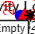


% --- Loading diagram plot (simplified envelope, x from nose) ------------------
% Four corner cases: Empty (OEW), Fuel only, Payload only, MTOW
m_payload = m_cargo_f + m_cargo_a + m_pass;
x_payload = (m_cargo_f*x_cargo_f + m_cargo_a*x_cargo_a + m_pass*x_pass)/m_payload;

% Mass [kg] and CG position from the nose [m] for each corner
mE = M_oew;
xE = x_oew;

mF = M_oew + m_fuel;
xF = (M_oew*x_oew + m_fuel*x_fuel)/mF;

mP = M_oew + m_payload;
xP = (M_oew*x_oew + m_payload*x_payload)/mP;

mM = M_oew + m_payload + m_fuel;
xM = (M_oew*x_oew + m_payload*x_payload + m_fuel*x_fuel)/mM;

x_fore = min([xE xF xP xM]);
x_aft  = max([xE xF xP xM]);

figure; hold on; grid on; box on;

% Masses in tonnes for plotting
tE = mE/1e3;  tF = mF/1e3;  tP = mP/1e3;  tM = mM/1e3;

% Envelope edges: Empty -> Payload -> MTOW (via payload), Empty -> Fuel -> MTOW (via fuel)
plot([xE xP], [tE tP], 'b-', 'LineWidth', 1, 'HandleVisibility','off');   % add payload
plot([xE xF], [tE tF], 'b-', 'LineWidth', 1, 'HandleVisibility','off');   % add fuel
plot([xP xM], [tP tM], 'r-', 'LineWidth', 1, 'HandleVisibility','off');   % then add fuel
plot([xF xM], [tF tM], 'r-', 'LineWidth', 1, 'HandleVisibility','off');   % then add payload

% Fore / aft limit lines
xline(x_fore,'--r',sprintf('Fore x_{cg} = %.4f m',x_fore), ...
    'LabelVerticalAlignment','middle','LabelHorizontalAlignment','left', ...
    'Color','r','HandleVisibility','off');
xline(x_aft,'--r',sprintf('Aft x_{cg} = %.4f m',x_aft), ...
    'LabelVerticalAlignment','middle','LabelHorizontalAlignment','right', ...
    'Color','r','HandleVisibility','off');

% Corner markers
h1 = plot(xE,tE,'o','MarkerFaceColor','b','MarkerEdgeColor','b','MarkerSize',7);
h2 = plot(xF,tF,'s','MarkerFaceColor','r','MarkerEdgeColor','r','MarkerSize',7);
h3 = plot(xP,tP,'^','MarkerFaceColor','r','MarkerEdgeColor','r','MarkerSize',7);
h4 = plot(xM,tM,'k*','MarkerSize',8,'LineWidth',1.2);

xlabel('Centre of gravity position from nose, x_{cg} (m)');
ylabel('Weight (tonnes)');
title('Centre of Gravity Loading Envelope');
legend([h1 h2 h3 h4],{'Empty','Fuel Only','Payload Only','MTOW'},'Location','northeast');

pad = 0.1*(x_aft - x_fore);
xlim([x_fore - pad, x_aft + pad]);
ylim([0.9*tE, 1.1*tM]);
hold off


fprintf('Envelope: fore %.3f m, aft %.3f m from nose (%.1f%% to %.1f%% MAC)\n', ...
    x_fore, x_aft, 100*(x_fore-LEMAC)/MAC, 100*(x_aft-LEMAC)/MAC);

Envelope: fore 29.739 m, aft 31.870 m from nose (-6.1% to 23.2% MAC)



% ========================================================================
%  LONGITUDINAL STABILITY: STATIC MARGIN AT THE FORE AND AFT CG LIMITS
%  ========================================================================
% Uses x_fore / x_aft (m from nose) from the loading envelope above.
% Shared geometry (xacw, xach, xacv, MAC, b, AR, lambda, Lambda_w, AR_h, V_h,
% V_v, Sw_m2) comes from the top of this script, so there is one source of truth.

% --- Stability inputs (copied from the stability script) ---
Sref  = Sw_m2;            % reference wing area [m^2]
Sh    = S_ht/3.281^2;     % H-stab area [m^2] (S_ht is in ft^2 above)
lh    = xach - xacw;      % wing a.c. to H-stab a.c. [m]
hh    = 4.0;              % vertical distance between wing and H-stab a.c. [m] [guess]

Kf    = 1.2;              % fuselage pitching moment factor
Lf    = 64.84;            % fuselage length [m]
wf    = 5.834;            % fuselage max width [m]
CMaf  = (Kf*Lf*wf^2)./(MAC*Sref);

CLaw   = 7;               % dCL/dalpha wing at M = 0.82 [guess]
CLawm0 = 6.69889;         % dCL/dalpha wing at M = 0
CLah   = 4;               % dCL/dalpha H-stab at M = 0.82 [guess]
etah   = 0.9;             % tail efficiency factor

% --- Downwash gradient (Raymer) ---
KA      = 1./AR - 1./(1 + AR^1.7);
Klambda = (10 - 3*lambda)./7;
Kh      = (1 - abs(hh./b))./((2*lh./b)^(1/3));
de_da   = 4.44.*(KA*Klambda*Kh*sqrt(cosd(Lambda_w))).^1.19*(CLaw/CLawm0);

% --- Neutral point and lift-curve slope ---
dCL_da = CLaw + etah*CLah*(1 - de_da)*(Sh/Sref);
xnp    = MAC.*(CLaw.*(xacw/MAC) - CMaf + etah*CLah*(1 - de_da)*(Sh/Sref).*(xach/MAC)) ./ dCL_da;

% --- Static margin at the CG limits (via the neutral point) ---
xcg_lim = [x_fore, x_aft];                      % [fore, aft], m from nose

dCM_da_lim = -dCL_da.*(xnp - xcg_lim)./MAC;
SM_lim     = -dCM_da_lim./dCL_da;               % = (xnp - xcg)/MAC

% Power-on estimate (-0.02 for jets)
SM_pon_lim = SM_lim - 0.02;

pMAC_lim = 100*(xcg_lim - LEMAC)/MAC;           % LEMAC defined in the CG section

Tsm = table({'Fore';'Aft'}, xcg_lim', pMAC_lim', SM_lim', SM_pon_lim', ...
    'VariableNames', {'Limit','xcg_m','xcg_pctMAC','SM','SM_pwr_on'});
disp(Tsm);

     Limit      xcg_m     xcg_pctMAC      SM       SM_pwr_on
    ________    ______    __________    _______    _________

    {'Fore'}    29.739     -6.1152      0.51955     0.49955 
    {'Aft' }     31.87      23.209      0.22631     0.20631 




fprintf('Neutral point: %.2f m from nose (%.1f %% MAC)\n', xnp, 100*(xnp - LEMAC)/MAC);

Neutral point: 33.51 m from nose (45.8 % MAC)


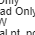

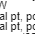

if xcg_lim(2) >= xnp
    warning('Aft CG limit is at or behind the neutral point: aircraft is statically unstable.');
end

% ========================================================================
%  ADDENDUM: LOADING ENVELOPE WITH NEUTRAL POINTS (power off / on)
%            AND WITH LIFTING-SURFACE AERODYNAMIC CENTRES
%  ========================================================================
% Plot 1: loading envelope + neutral points (power off and power on)
% Plot 2: same as plot 1 + a.c. of wing, H-tail and V-tail
% Needs: tE tF tP tM xE xF xP xM x_fore x_aft (loading envelope section),
%        xnp SM_lim SM_pon_lim (stability section)

xnp_pon = xnp - 0.02*MAC;     % power-on neutral point (SM reduced by 0.02)

for p = 1:2
    figure; hold on; grid on; box on;

    % Envelope edges
    plot([xE xP], [tE tP], 'b-', 'LineWidth', 1, 'HandleVisibility','off');
    plot([xE xF], [tE tF], 'b-', 'LineWidth', 1, 'HandleVisibility','off');
    plot([xP xM], [tP tM], 'r-', 'LineWidth', 1, 'HandleVisibility','off');
    plot([xF xM], [tF tM], 'r-', 'LineWidth', 1, 'HandleVisibility','off');

    % Fore / aft Code line 317 zW_nlg_dep = -(0.5o*D + 0.4*H_gear);% [guess]
ckpit
G limits
    xline(x_fore,'--r','HandleVisibility','off');
    xline(x_aft, '--r','HandleVisibility','off');

    % Corner markers
    plot(xE,tE,'o','MarkerFaceColor','b','MarkerEdgeColor','b','MarkerSize',7,'DisplayName','Empty');
    plot(xF,tF,'s','MarkerFaceColor','r','MarkerEdgeColor','r','MarkerSize',7,'DisplayName','Fuel Only');
    plot(xP,tP,'^','MarkerFaceColor','r','MarkerEdgeColor','r','MarkerSize',7,'DisplayName','Payload Only');
    plot(xM,tM,'k*','MarkerSize',8,'LineWidth',1.2,'DisplayName','MTOW');

    % Neutral points (SM = 0) with the SM at the fore/aft limits in the legend
    xline(xnp, '-.', 'Color',[0 0.6 0], 'LineWidth',1.5, 'DisplayName', ...
        sprintf('Neutral pt, power off (SM fore/aft = %.1f / %.1f %% MAC)', ...
        100*SM_lim(1), 100*SM_lim(2)));
    xline(xnp_pon, '-.', 'Color',[0.85 0.33 0.1], 'LineWidth',1.5, 'DisplayName', ...
        sprintf('Neutral pt, power on (SM fore/aft = %.1f / %.1f %% MAC)', ...
        100*SM_pon_lim(1), 100*SM_pon_lim(2)));

    xs = [x_fore x_aft xnp xnp_pon];

    if p == 2
        % Lifting-surface aerodynamic centres
        xline(xacw, ':', 'Color',[0.49 0.18 0.56], 'LineWidth',1.5, 'DisplayName', ...
            sprintf('Wing a.c. (%.2f m)', xacw));
        xline(xach, ':', 'Color',[0 0.45 0.74],    'LineWidth',1.5, 'DisplayName', ...
            sprintf('H-tail a.c. (%.2f m)', xach));
        xline(xacv, ':', 'Color',[0.3 0.3 0.3],    'LineWidth',1.5, 'DisplayName', ...
            sprintf('V-tail a.c. (%.2f m)', xacv));
        xs = [xs xacw xach xacv];
    end

    xlabel('Centre of gravity position from nose, x_{cg} (m)');
    ylabel('Weight (tonnes)');
    if p == 1
        title('CG Loading Envelope with Neutral Points');
    else
        title('CG Loading Envelope with Neutral Points and Lifting Surfaces');
    end

    pad = 0.05*(max(xs) - min(xs));
    xlim([min(xs) - pad, max(xs) + pad]);
    ylim([0.9*tE, 1.1*tM]);
    legend('Location','best');
    hold off
end